# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

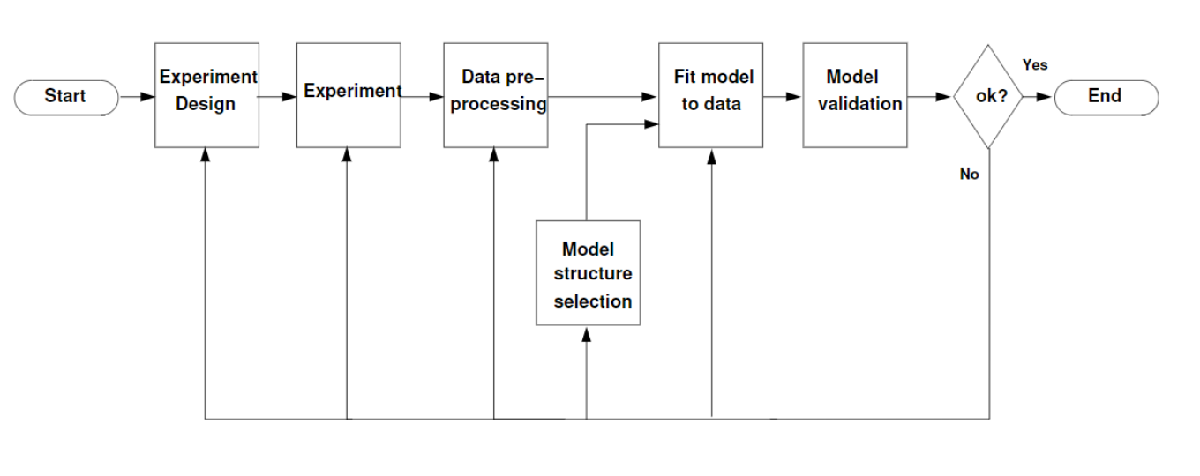

## Part 0: Setup

Please insert your names and student numbers below.

Name: Josephine King

Student Number: 6250513

Name: Thomas Prins 

Student Number: 5885221

% Clear workspace
clearvars; clc; close all;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 5885221;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to determine a suitable sampling frequency and motivate your answer.

*Answer**:*

*First, we analyze the step response of the system with a relatively high sampling frequency (*$f_s$* = 10 Hz) and run the simulation for *$T$* = 1000s so that we can see the transient and steady state response. From the response, we can see that the system has a lot of oscillation and overshoot in the transient response. Using the overshoot *$M_p$* and oscillation period, we can estimate the damping ratio *$\zeta$*and natural frequency *$\omega_n$*, which we can then use to estimate the bandwidth, *$\omega_B \ldotp$ 


$$\zeta =-\frac{\ln \left(M_p \right)}{\sqrt{\pi^2 +{\ln \left(M_p \right)}^2 }}$$


$\omega_n \approx \frac{2\pi }{t_{\textrm{cycle}} }$ (for small damping ratio)


$$\omega_B =\omega_n \sqrt{1-2\zeta^2 +\sqrt{{\left(2\zeta^2 -1\right)}^2 +1}}$$


We choose a sampling frequency 10 times the bandwidth: $f_s =\frac{{10\omega }_b }{2\pi }$. We can also estimate the time constant $\tau \approx \frac{1}{\omega_n \zeta }$. We then choose an experiment duration of $T=10\tau$.

Using this technique, we arrive at $f_s =1\ldotp 84\;\textrm{Hz}$ and $T=212\ldotp 52\;s$

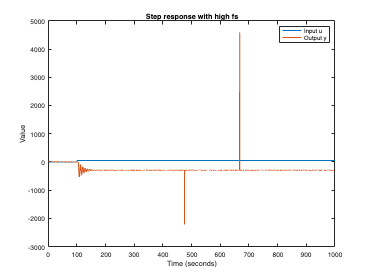

T = 1000;
fs = 10;
N = round(T*fs);
input_mag = 50;
step_start = round(N/10);
t = (1/fs)*(0:N-1);

u_step = input_mag*ones(1,N);
u_step(1:step_start) = 0;
y_step = exciteSystem(STUDENTID,u_step,fs);

plot(t,u_step,t,y_step)
title("Step response with high fs")
xlabel("Time (seconds)")
ylabel("Value")
legend(["Input u", "Output y"])

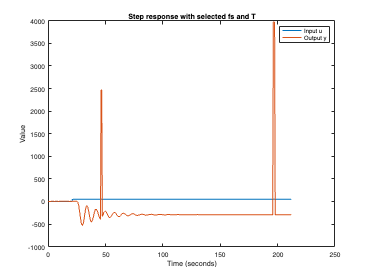


% Find the natural frequency from the time constant tau
t_cycle = 32.6 - 24.2; % duration of cycle
wn = 2*pi/t_cycle;
% Find the damping ratio from the overshoot
Mp = (533 - 292.8)/292.8;
dr = -log(Mp)/(sqrt(pi^2+(log(Mp))^2));

% Get bandwidth 
wb = wn*sqrt(1-2*dr^2+sqrt((2*dr^2-1)^2+1));
% Get sampling frequency
fs = 10*wb/(2*pi);

% Get duration from 10x time constant
tau = 1/(wn*dr);
T = 10*tau;

% Plot again with selected sampling frequency
N = round(T*fs);
t = (1/fs)*(0:N-1);
step_start = round(N/10);

u_step = input_mag*ones(1,N);
u_step(1:step_start) = 0;
y_step = exciteSystem(STUDENTID,u_step,fs);

plot(t,u_step,t,y_step)
title("Step response with selected fs and T")
xlabel("Time (seconds)")
ylabel("Value")
legend(["Input u", "Output y"])

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

*For our persistingly exciting input signal, we chose a Pseudo Random Binary Sequence (PRBS). We chose this sequence because it mimics a truly random sequence (like white noise) but is actually deterministic and possible to implement in the real world. To create the PRBS signal, we used the MATLAB prbs(O,N) command with an order of 10. This means the sequence repeats after *$2^{10}$ *cycles. As a result, the order of persistency of excitation is *$2^{10} -1=1023$*. We ran a test below to confirm that the Hankel matrix is full rank for *$s=1023$* and rank deficient for higher s. Because our input sequence has a length of *$N=392$*, this order of persistency of excitation is sufficient. *

% Use MATLAB's prbs function to create a Pseudo Random Binary Sequence
u = input_mag.*prbs(10,N);
y = exciteSystem(STUDENTID,u,fs);

% Create an even longer sequence to test persistency of excitation 
u_poe = input_mag.*prbs(10,2^12);
order_poe = 0;
% Iterate from s = 1 - 2^20-1
for i = 1:11
    s = 2^i-1;
    % Create the Hankel matrix for s and choose a sufficiently large N
    U = construct_hankel(u_poe,s,2^11+1);
    % If it's full row rank, the order is s, now progress to a higher s
    if (rank(U) == s) 
        order_poe = s;
    % If it's not full row rank, the order is less than s
    else
        break
    end
end
sprintf("Order of persistency of excitation is %0d", order_poe)

ans = "Order of persistency of excitation is 1023"

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

*We noticed that the spikes have a magnitude of > 20 times our input signal magnitude. So, we identify the corrupted values by searching for outputs with a magnitude greater than 20*input_mag. Then, we remove these values from the output signal and fill them in using interpolation (MATLAB's interpo1 function). We used the pchip method, which is a type of polynomial interpolation. *

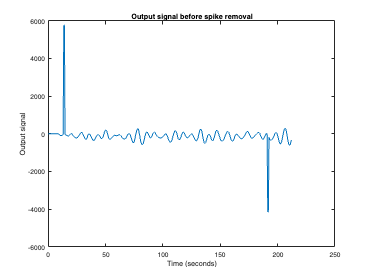

% Function is at the end of file but copied here for viewing
% function y_clean = clean_y(y, input_mag)
% 
%     corrupted = find(abs(y) > 20*input_mag);
%     x = 1:length(y);
%     y_clean = y;
% 
%     y_clean(corrupted) = NaN;
%     cleaned_vals = interp1(x(~isnan(y_clean)), y_clean(~isnan(y_clean)), corrupted, 'pchip');
%     y_clean(corrupted) = cleaned_vals;
% 
% end
y_clean = clean_y(y, input_mag);

plot(t,y)
title("Output signal before spike removal")
ylabel("Output signal")
xlabel("Time (seconds)")

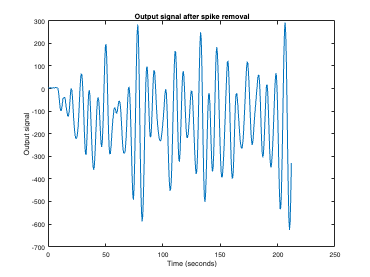


plot(t,y_clean)
title("Output signal after spike removal")
ylabel("Output signal")
xlabel("Time (seconds)")

y = y_clean;

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

*To determine the time delay of our system, we can analyze the step response, which we've plotted below. We can see that the output doesn't respond until about 4.33 seconds later, which corresponds to a delay of about 8 time steps. We can remove the time delay in y by shifting it back in time by 8 time steps. *

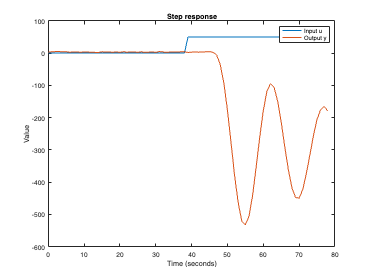

y_step = exciteSystem(STUDENTID,u_step,fs);
y_step = clean_y(y_step, input_mag);

plot(0:round(N/5),u_step(1:round(N/5)+1),0:round(N/5),y_step(1:round(N/5)+1))
title("Step response")
xlabel("Time (seconds)")
ylabel("Value")
legend(["Input u", "Output y"])

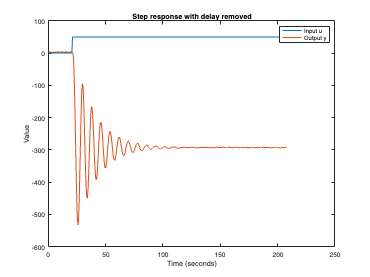


% Step response starts at time step 38, see response start at time step 46
delay = 46 - 38;
plot(t,u_step,t(1:end-delay+1),y_step(delay:end))
title("Step response with delay removed")
xlabel("Time (seconds)")
ylabel("Value")
legend(["Input u", "Output y"])


% Function is at end of file but copied here for convenience
% % Remove delay from y
% function y_minus_delay = remove_delay(y, delay)
%     y_minus_delay = y(delay:end);
% end
y = remove_delay(y, delay);
t_minus_delay = t(1:end-delay+1);


Remove the DC offset from the output (if any).

*Answer**:*

*The DC offset is the mean of the output. To remove the DC offset, we simply subtract the mean of y from y. *

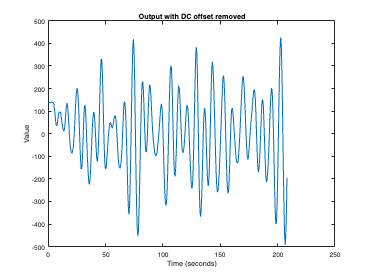

% Function is at end of file but copied here for convenience
% % Remove DC offset from y
% function y_minus_dc_offset = remove_dc_offset(y)
%     % DC offset is the mean of the output
%     dc_offset = mean(y);
%     % Remove DC offset
%     y_minus_dc_offset = y - dc_offset;
% end

y = remove_dc_offset(y);

plot(t_minus_delay,y)
title("Output with DC offset removed")
xlabel("Time (seconds)")
ylabel("Value")

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

*For a system to be linear, it must satisfy the properties of additivity and scaling.*

*Additivity: *$u_1 \to y_1 ,u_2 \to y_2 \;$then $\left(u_1 +u_2 \right)\to \left(y_1 +y_2 \right)$

Scaling: $u_1 \to y_1$ then ${k\;u}_1 \to {k\;y}_1$

To test if our system is linear, we will test these two properties. First, we will create two random inputs $u_1$and $u_2$. Then we will generate outputs from the following inputs:


$$\begin{array}{l}
y_1 =\textrm{exciteSystem}\left(u_1 \right)\\
y_2 =\textrm{exciteSystem}\left(u_2 \right)\\
y_3 =\textrm{exciteSystem}\left(u_1 +u_2 \right)\\
y_4 =\textrm{exciteSystem}\left(k\;u_1 \right)
\end{array}$$


So if we find that $y_1 +y_2 =y_3$, the system satisfies the additivity property. If $y_4 =k\;y_1$, it satisfies scaling. It needs to satisfy both properties to be linear. We can plot the results to compare them and also compare the RMSEs between the signals with some tolerance. 

From our plots, we can see that the signals we plotted align almost perfectly. This tells us that **our system is approximately linear**.

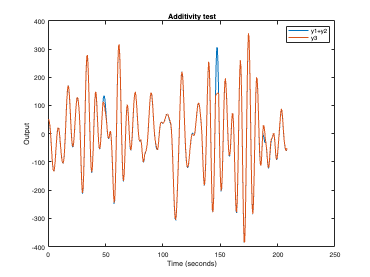

k1 = round((100-11)*rand+11);
k2 = round(10*rand+2);
u_long = input_mag.*prbs(k1,2*N);
u1 = u_long(1:N);
u2 = u_long(N+1:end);

tolerance = 1e-2;
y1 = filter_y(exciteSystem(STUDENTID,u1,fs), delay, input_mag);
y2 = filter_y(exciteSystem(STUDENTID,u2,fs), delay, input_mag);
y3 = filter_y(exciteSystem(STUDENTID,u2+u1,fs), delay, input_mag);
y4 = filter_y(exciteSystem(STUDENTID,k2*u1,fs), delay, k2*input_mag);

figure(1)
plot(t_minus_delay,y1+y2,t_minus_delay,y3)
xlabel("Time (seconds)")
ylabel("Output")
title("Additivity test")
legend(["y1+y2", "y3"])

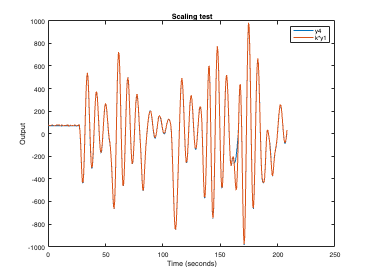


figure(2)
plot(t_minus_delay,y4,t_minus_delay,k2*y1)
xlabel("Time (seconds)")
ylabel("Output")
title("Scaling test")
legend(["y4", "k*y1"])


rmse1 = rmse(y2+y1,y3);
rmse2 = rmse(k2*y1,y4);
combined_tol1 = tolerance*input_mag*N;
combined_tol2 = tolerance*input_mag*N*k2;
if rmse1 < combined_tol1; success1 = "successful"; else success1 = "not successful"; end
if rmse2 < combined_tol2; success2 = "successful"; else success2 = "not successful"; end

fprintf('linear experiment %s 1/2, RMSE = %0d, tolerance = %0d', success1, rmse1, combined_tol1)

linear experiment successful 1/2, RMSE = 1.476889e+01, tolerance = 196

fprintf('linear experiment %s 2/2, RMSE = %0d, tolerance = %0d', success2, rmse2, combined_tol2)

linear experiment successful 2/2, RMSE = 2.924458e+01, tolerance = 980

if ((rmse1 < combined_tol1) && (rmse2 < combined_tol2))
    fprintf('system is linear')
else
    fprintf('system is nonlinear')
end

system is linear

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

*We can generate output data using the persistently exciting input signal that we selected earlier. This signal has length N, which is the number of samples based on our selected experiment duration and sampling frequency. We will use the first 80% of this data for training our model and the other 20% for validation of the model. *

% Use 80% for training and 20% for validation
start_val = round(0.8*N);
uTrain = u(1:start_val-1);
yTrain = y(1:start_val-1);
uVal = u(start_val:end);
yVal = y(start_val:end);

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

*To determine the model order, we constructed the U and Y Hankel matrices and derived the L_32 matrix. We did a singular value decomposition of L_32 and plotted these values. From the plot, we can see that the first 2 singular values are significantly larger than the others. So, we initially tried a system order of n = 2, but we found that we got better results with ****n = 4****. This is reasonable based on the plot as the first four singular values are all within roughly one order of magnitude. After a few iterations, we also found that a block size of s = 40 gives us good results.*

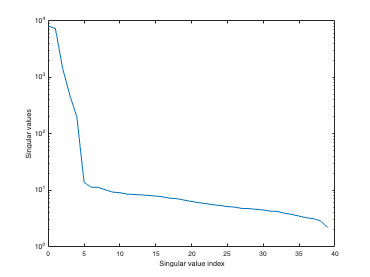

s = 40;
N = length(uTrain) - 2*s + 1;
% Construct Hankel matrices
U_hankel = hankel(uTrain(1:2*s), uTrain(2*s:N+2*s-1)); %hankelmatrix of inputs
Y_hankel = hankel(yTrain(1:2*s), yTrain(2*s:N+2*s-1)); %hankelmatrix of outputs
Uf = U_hankel(s+1:2*s,:);
Up = U_hankel(1:s,:);
Yf = Y_hankel(s+1:2*s,:);
Yp = Y_hankel(1:s,:);
% Find L_32 matrix
A = [Uf; Up; Yp; Yf];
[Q,R] = qr(A');
L = R';
L_32 = L(3*s+1:end, size(Uf,1)+1:size(Uf,1)+size(Up,1)+size(Yp,1));
% Perform SVD and analyze singular values
[U,S,V] = svd(L_32, 'econ');
singular_vals = diag(S,0);
x_vals = 0:(size(singular_vals,1)-1);

semilogy(x_vals, singular_vals)
xlabel("Singular value index")
ylabel("Singular values")


% See when the singular values drop by one order of magnitude in the plot
% Based on this choose n = 4
n = 4;

Identify the model. You are free to choose the identification method.

*Answer**:*

*We chose the PO-MOESP method with an order of 4. This gives us the following model:*


$$x_{k+1} ={A\;x}_k +{B\;u}_k$$



$$y_{k\;} =C\;x_k +D\;u_k$$


The values of system matrices $A,B,C,\textrm{and}\;D$and the starting condition $x_0$ are printed below:

% Use PO-MOESP method
[A,B,C,D,x0]=pomoesp(uTrain,yTrain,s,n);
A

A =     0.9105    0.4238    0.0342    0.0459
   -0.3812    0.8667   -0.0297   -0.2790
   -0.0003   -0.0150    1.0046   -0.1435
    0.0007    0.0188    0.0657    0.4678


B

B =    -3.9552
   -5.3999
    0.0442
    0.9393


C

C =     0.1902   -0.2661   -0.1259   -0.7914


D

D = 0.0560

x0

x0 =    72.5203
   85.4952
 -805.7729
  -38.3891


## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

*The VAF for the identification data and for the training data are both very high (> than 99), which indicates that our model performs well on both the training data and the validation data. The VAF is similar for both the training data and validation data, which shows that our model is not overfit to the training data. *

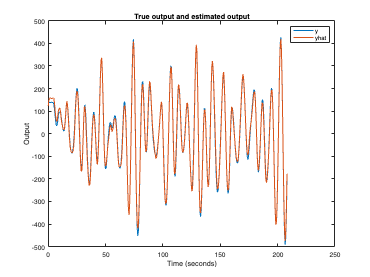

[yhat, xhatTotal] = simsystem(A,B,C,D,x0,u);
yhat = yhat(1:end-delay+1);
yhatTrain = yhat(1:start_val-1);
yhatVal = yhat(start_val:end);

plot(t_minus_delay, y, t_minus_delay, yhat)
title("True output and estimated output")
xlabel("Time (seconds)")
ylabel("Output")
legend(["y", "yhat"])


VAFTrain = VAF(yTrain, yhatTrain)

VAFTrain = 99.4702

VAFVal = VAF(yVal, yhatVal)

VAFVal = 99.7196

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

*We can calculate the residuals *$\left(e\left(k\right)=y\left(k\right)-\overset{\wedge }{y} \left(k\right)\right)$*and their autocorrelation using MATLAB's xcorr function. We use "coeff" mode to normalize the autocorrelation function to a maximum value of 1. From the plot, we can see that the autocorrelation function approximates a unit pulse, with a large value at lag = 0 and small values for all other lags. This is the result we expect, as the residuals from different time steps shouldn't have a correlation if we have done a good job with our model (the residuals resemble white noise).*

resid = y - yhat;
[acf,lags] = xcorr(resid, "coeff");
mean(resid)

ans = 0.1514

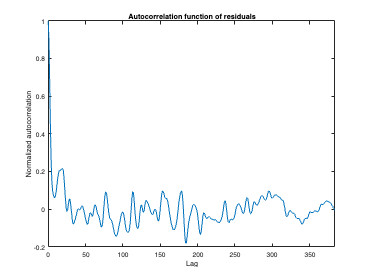

plot(lags,acf)
xlim([0,lags(end)])
xlabel("Lag")
ylabel("Normalized autocorrelation")
title("Autocorrelation function of residuals")

Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

*We can calculate the cross correlation between the residuals and the inputs using MATLAB's xcorr function. First, we want to remove the end of the input vector so that it's the same size as the residual vector (which was shortened due to the time shift). Then we want to normalize both the input vector and the residual vector to remove any scaling from the input magnitude or output.*

*We plotted a histogram of the cross correlation function. In this histogram, we can see that the normalized cross correlation values are quite small, in the range of -0.1 to 0.1. This indicates that there is little correlation between the inputs and the errors and the inputs and errors are basically statistically independent, which shows that our model is good. On top of that, the distribution of the cross correlation values appear to be zero-mean Gaussian.*

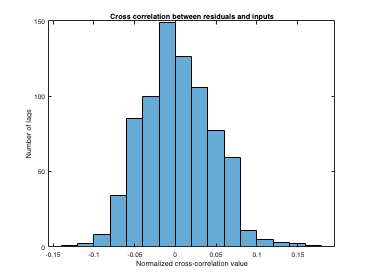

u_minus_delay = u(1:end-delay+1);
[ccf,lags] = xcorr(u_minus_delay./input_mag, resid./mean(abs(resid)), 'biased');

histogram(ccf)
xlabel("Normalized cross-correlation value")
ylabel("Number of lags")
title("Cross correlation between residuals and inputs")

**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

Yes

## Functions

Implement your functions in this section

### Prediction Error Methods

Implement your PEM functions below 

function [A,B,C,D,x0]=pomoesp(u,y,s,n)
% Function INPUT 
% u         system input (matrix of size N x m)
% y         system output (matrix of size N x l)
% s         block size (scalar)
% n         system order (scalar)
%
% Function OUTPUT
% A         System matrix A (matrix of size n x n)
% B         System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)  

    % Get the Hankel matrices
    N = length(u) - 2*s + 1;
    U_hankel = hankel(u(1:2*s), u(2*s:N+2*s-1)); %hankelmatrix of inputs
    Y_hankel = hankel(y(1:2*s), y(2*s:N+2*s-1)); %hankelmatrix of outputs

    % Get the L32 matrix
    Uf = U_hankel(s+1:2*s,:);
    Up = U_hankel(1:s,:);
    Yf = Y_hankel(s+1:2*s,:);
    Yp = Y_hankel(1:s,:);
    A = [Uf; Up; Yp; Yf];
    [Q,R] = qr(A');
    L = R';
    L_32 = L(3*s+1:end, size(Uf,1)+1:size(Uf,1)+size(Up,1)+size(Yp,1));
    [U,S,V] = svd(L_32, 'econ');

    % Get the A and C matrices
    C = U(1, 1:n);
    A = U(1:s-1, 1:n) \ U(2:end, 1:n);

    % Get x0, B, and D
    phi = [];
    N = size(y,1);
    for k = 1:N 
        middle_sum = zeros(1,n);
        for j = 1:k-1
            middle_sum = middle_sum + kron(u(j), C*A^(k-j-1));
        end
        phi_k = [C*A^(k-1), middle_sum, kron(u(k), 1)];
        phi = [phi; phi_k];
    end
    vec = phi \ y;
    x0 = vec(1:n);
    B  = vec(n+1:2*n);
    D  = vec(2*n+1:end);         

end

### Subspace ID Methods

Implement your Subspace ID functions below 

% Construct a Hankel matrix from U with order s and N samples
function U = construct_hankel(u, s, N)
    U = hankel(u(1:s), u(s:N+s-1));
end

% Clean the measurement error from y
function y_clean = clean_y(y, input_mag)

    corrupted = find(abs(y) > 20*input_mag);
    x = 1:length(y);
    y_clean = y;

    y_clean(corrupted) = NaN;
    cleaned_vals = interp1(x(~isnan(y_clean)), y_clean(~isnan(y_clean)), corrupted, 'pchip');
    y_clean(corrupted) = cleaned_vals;

end

% Remove delay from y
function y_minus_delay = remove_delay(y, delay)
    y_minus_delay = y(delay:end);
end

% Remove DC offset from y
function y_minus_dc_offset = remove_dc_offset(y)
    % DC offset is the mean of the output
    dc_offset = mean(y);
    % Remove DC offset
    y_minus_dc_offset = y - dc_offset;
end

% Clean, remove delay, and remove DC offset
function filtered_y = filter_y(y, delay, input_mag)
    filtered_y = clean_y(y, input_mag);
    filtered_y = remove_delay(filtered_y, delay);
    filtered_y = remove_dc_offset(filtered_y);
end

function [y,x] = simsystem(A,B,C,D,x0,u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (matrix of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (matrix of size N x n)
% y system output (matrix of size N x l)

    N = length(u); 
    n = size(A, 1); 
    l = size(C, 1);   

    x = zeros(N,n);
    y = zeros(N,l);

    x(1,:) = x0';

    for i = 1:N
        x(i+1,:) = (A*x(i,:)' + B*u(i))';
        y(i,:) = (C*x(i,:)' + D*u(i))';
    end
    
    x = x(1:N,:);
end

function rmse = RMSE(y,yhat)   
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% RMSE Root Mean Squared Error (scalar)

    squared_diff = (y - yhat).^2;
    mse = mean(squared_diff);
    rmse = sqrt(mse);
end

function vaf = VAF(y,yhat)
% Function INPUT
% y    measured system output (matrix of size N x l)
% yhat simulated system output (matrix of size N x l)
%
% Function OUTPUT
% VAF Variance Accounted For (scalar)
    vaf = (1 - (norm(y - yhat)^2)/norm(y)^2)*100;
end
